clc; clear all; close all;

% Exported Data Format: [ Vessel#  Frame#  MinFrameDistance MaxFrameDistance MeanIntensityForEachDistanceFromVessel  ]

## Import data

% .txt file (Recommended for speed):

% Input data folder name (INCLUDE FOLDER PATH AND NAME):
sourcefolder = 'C:\Users\exx\Desktop\Zach - Active Analysis\2290\Intensity_distance_data';

% Input Cortical Layer file name (INCLUDE FOLDER PATH AND NAME):
cortical_sourcefolder = 'C:\Users\exx\Desktop\Zach - Active Analysis\2290\vessel_cortical_data';

% Max Distance From Vessel (in microns) (Recommended Value 100):

ves_dist = [ 100 ];

min_dist = [ -10 ];

% Resolution in microns? (Recommended Value: 1):

res = [ 1 ];

% Frame width (# Microns):

frame_w = [ 10 ];

% Data Output Name (True, unshuffled data only) (Include Name + Path):
% Vessel number and data type will be appended, so do not include in names.
% NEED FOLDER WITH SAME NAME FOR EACH DATA TYPE: XDATA, YDATA, AND ERRORS
% ex. you need folders stat_data_xdata, stat_data_ydata, and
% stat_data_errors if stat_data is the folder name.

% Folder:
outputfoldername = 'C:\Users\exx\Desktop\Zach - Active Analysis\2290\2290_cortical_test_data_output';


% % Set number of bins by increment of intensity
% nbins = round((max(Tau_data(:,4)) - min(Tau_data(:,4)))/50);

## Load data

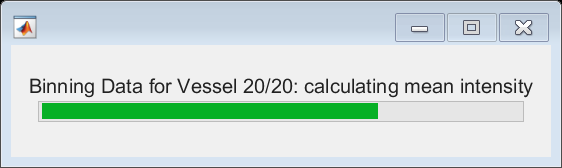

% # Bins along vessel
nbins_length = 5;

f = waitbar(0,'Calculating Statistics: Reading Data 0 %');

fcontent = dir(fullfile(sourcefolder, '*.txt')); %fcontent is a column vector of structures

l1 = 1;

Tau_data = [];

n = length(fcontent');

%b = 1;
endrow = 0;

for b = 1:n
    sizes = [];
        Tau_data = [];
        bin_edges = [];
        bin_numbers = [];
        clc
        % close all

%i = 7;

% Check if data matches

filename = fcontent(b).name;

fcontent2 = dir(fullfile(cortical_sourcefolder, '*.txt')); %fcontent is a column vector of structures
filename2 = fcontent2(b).name;

[pathstr,name,ext] = fileparts(filename);

name_parts = regexp(name,'_','split');

vesnum1 = name_parts{3};

[pathstr2,name2,ext2] = fileparts(filename2);

name_parts2 = regexp(name2,'_','split');

vesnum2 = name_parts2{3};

if vesnum1 ~= vesnum2
    error(sprintf('VESSEL MATCH ERROR: Cortical layer and intensity data do not match (cortical: Vessel %s intensity: Vessel %s )',vesnum2,vesnum1));
    break
end

% Load intensity data 

Tau_data = readmatrix(fullfile(sourcefolder,filename));

% Load vessel cortical data

cortical_data = readmatrix(fullfile(cortical_sourcefolder,filename2));


    waitbar(0,f,sprintf('Calculating Statistics: Reading Data %d %%',floor(i/n*100)));


waitbar(0.1,f,'Calculating Statistics: Preparing Data');

% Remove data where Tau is less than min_dist and greater than ves_dist
% away from vessel
Tau_data_backup = Tau_data;
idx = find( Tau_data(:,6) <= min_dist);
Tau_data(idx,:) = [];
idx = find(Tau_data(:,6) > ves_dist );
Tau_data(idx,:) = [];

## Bin data by surface frames

content = dir(fullfile(sourcefolder, '*.txt')); %fcontent is a column vector of structures
filename = fcontent(b).name;
[pathstr,name,ext] = fileparts(filename);

name_parts = regexp(name,'_','split');
vesnum = str2num(name_parts{3});

waitbar(0.6,f,sprintf('Binning Data for Vessel %d/%d: distance away from vessel',b,n));


## Bin by distance away


edges_away = min_dist-0.5:res:ves_dist+0.5;

idx_tau_away = discretize(Tau_data(:,6),edges_away);

waitbar(0.65,f,sprintf('Binning Data for Vessel %d/%d: distance along vessel',b,n));


## Bin by distance along


maxlength = (ceil(max(cortical_data(:,6)/frame_w))*frame_w);

edges_along = 0:frame_w:maxlength;

idx_cortical_along = discretize(cortical_data(:,6),edges_along);

idx_tau_along = discretize(Tau_data(:,5),edges_along);


## Store bin coordinates & calculate mean intensity

waitbar(0.7,f,sprintf('Binning Data for Vessel %d/%d: calculating mean intensity',b,n));

Tau_data(:,7:8) = [idx_tau_along idx_tau_away];

cortical_data(:,7) = [idx_cortical_along];

Tau_data(any(isnan(Tau_data), 2), :) = [];
cortical_data(any(isnan(cortical_data), 2), :) = [];

final_data(endrow+1:endrow+length(edges_along)-1,:) = zeros(length(edges_along)-1,length(edges_away)+4);

for i = 1:maxlength/frame_w
    
    idx = find(cortical_data(:,7) == i);
    if isempty(idx)
        cortical_layer = 0;
    else
    cortical_layer = round(mean(cortical_data(idx,5)));
    end
    final_data(endrow+i,1:5) = [vesnum i cortical_layer i*frame_w-frame_w  i*frame_w];

end

intensity_bins = cell(length(edges_along)-1,length(edges_away)-1);

if isempty(Tau_data)
endrow = length(final_data(:,1));
Tau_data = [];
continue
end

for i = 1:length(Tau_data(:,1))

    tau_data_temp = Tau_data(i,:);
    intensity_bins{tau_data_temp(:,7),tau_data_temp(:,8)}(end+1,:) =  tau_data_temp(:,4);
    
end

intensity_means =  cellfun(@(x) mean(x, 'all'), intensity_bins);

intensity_means(isnan(intensity_means))=0;

[r,c] = size(intensity_means);

final_data(endrow+1:endrow+length(intensity_means(:,1)),6:c+5) = intensity_means;

endrow = length(final_data(:,1));
Tau_data = [];

end

## Create Headers

intensity_headers = [min_dist:ves_dist];
intensity_headerstemp = {};
sampleID = name_parts{1};

outputname = append(sampleID,'_intensity_binning_output');

for i = 1:length(intensity_headers)
    intensity_headerstemp(:,i) = {append(sprintf('%g',intensity_headers(1,i)),' um MeanIntensity')};
end
intensity_headers = intensity_headerstemp;
headers = cell2table({ sampleID 'Vessel#'  'Frame#' 'Cortical Layer' 'MinFrameDistance' 'MaxFrameDistance' intensity_headers{:}});

## Save Data (headers exported in separate file)

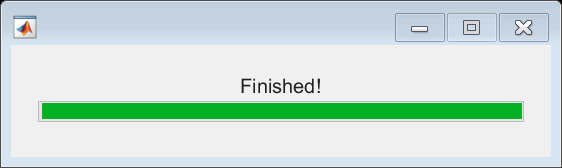

writetable(headers,append(outputfoldername,'/',outputname,'_HEADERS.csv'));
csvwrite(append(outputfoldername,'/',outputname,'.csv'),final_data);

waitbar(1,f,'Finished!');